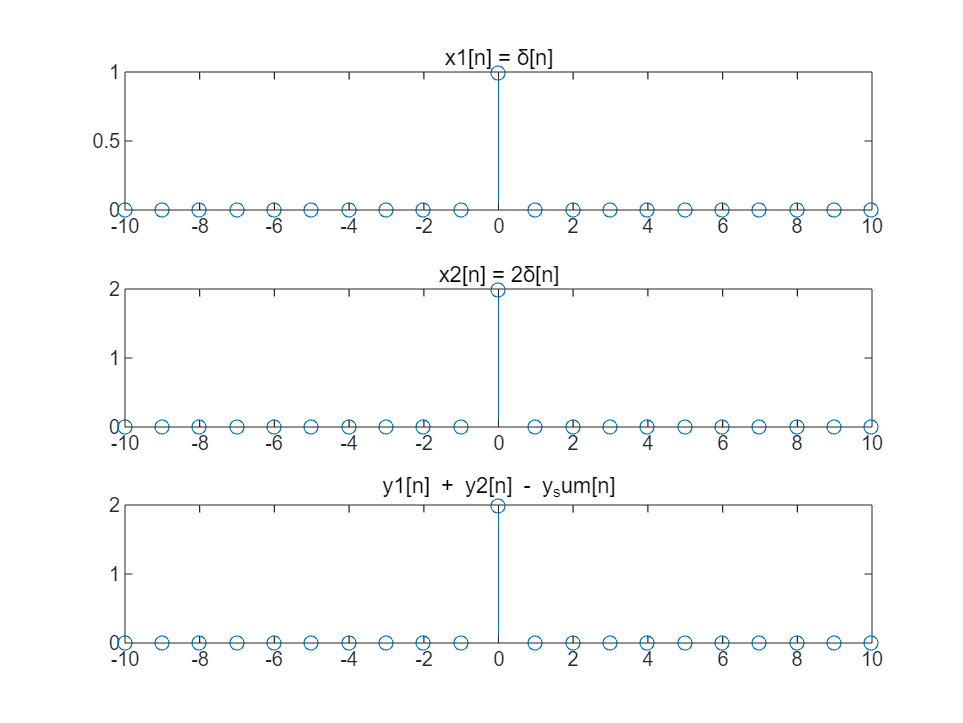

% 定义信号
n = -10:10; % 定义时间序列
x1 = [zeros(1,10), 1, zeros(1,10)]; % δ[n]
x2 = [zeros(1,10), 2, zeros(1,10)]; % 2δ[n]

% 计算输出
y1 = sin(pi/2 * x1);
y2 = sin(pi/2 * x2);
y_sum = sin(pi/2 * (x1 + x2)); % 线性组合的输出

% 计算线性组合的理论输出
y_linear_combination = sin(pi/2 * x1) + sin(pi/2 * x2);

% 绘制信号
figure;
subplot(3,1,1);
stem(n, x1);
title('x1[n] = δ[n]');
subplot(3,1,2);
stem(n, x2);
title('x2[n] = 2δ[n]');
subplot(3,1,3);
stem(n, y1 + y2 - y_sum);
title('y1[n] + y2[n] - y_sum[n]');


% 判断是否线性
if norm(y_sum - y_linear_combination) < 1e-10
    disp('系统是线性的');
else
    disp('系统不是线性的');
end

系统不是线性的
